licz = [1];

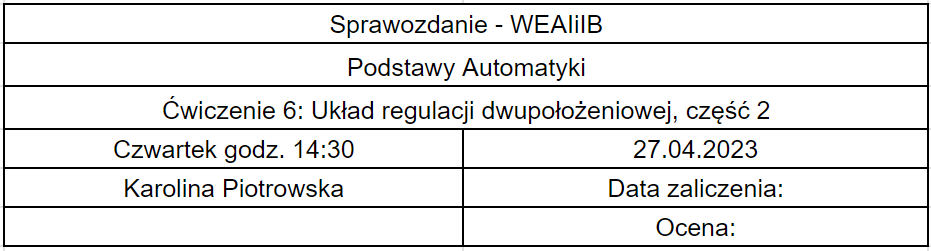

## Cel ćwiczenia

Ćwiczenie miało na celu rozwinięcie zagadnień prezentowanych podczas ćwiczeń rachunkowych "Stabilność układu regulacji z liniowym obiektem i nieliniowym regulatorem statycznym".

## Wstęp teoretyczny

Dany jest zamknięty układ regulacji złożony z liniowego obiektu  transmitancji opisanej jednym z poniższy h wzorów:

- 
$$G(s) = \frac{1}{s^3 + 3s^2 + 3s + 1}$$


- 
$$G(s) = \frac{1}{s(s^2 + 2s + 1)}$$


- 
$$G(s) = \frac{1}{(s+1)(s+2)(s+3)(s+4)}$$


oraz regulatora dwupołożeniowego bez histerezy i z histerezą o charakterystyce symetrycznej. 

## Przebieg ćwiczenia

### Transmitancja pierwsza

mian1 = [1 3 3 1];
mian2 = [1 2 1 0];
mian3 = [1 10 35 50 24];
h = 0.0;
ym = 2.1 * pi;

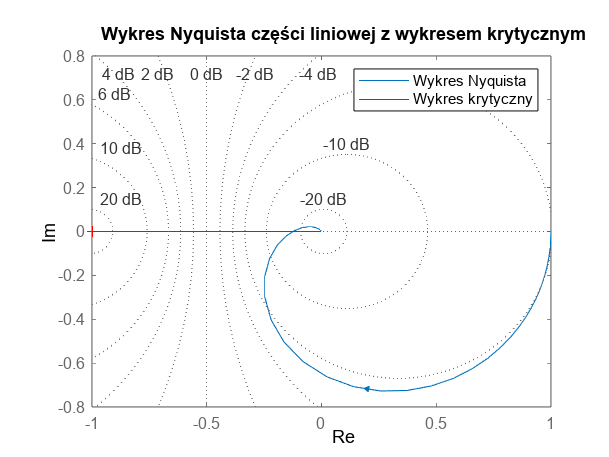

c = (-pi * h) / (4 * ym);
n = nyquistplot(tf([licz], [mian1]));
opt = getoptions(n);
opt.ShowFullContour = 'off';
setoptions(n, opt);

hold on;
plot([-1 0], [c c], 'r');
axis([-1 1 -0.8 0.8]);
grid on;
title('Wykres Nyquista części liniowej z wykresem krytycznym');
xlabel('Re');
ylabel('Im');
legend('Wykres Nyquista', 'Wykres krytyczny');
hold off;

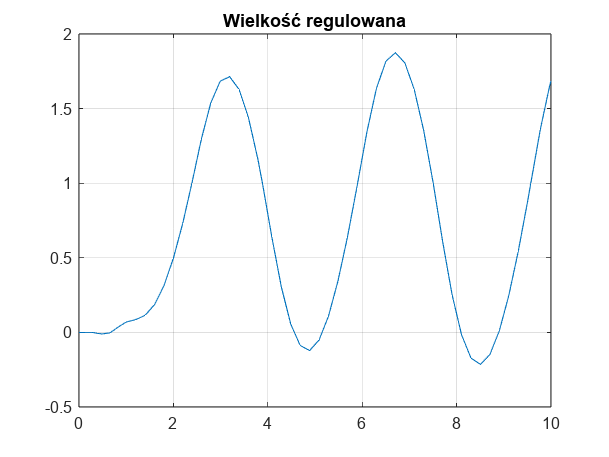


out1 = sim("lab6_model.slx");
figure
plot(out1.y.time, out1.y.signals.values);
title('Wielkość regulowana');
grid on;

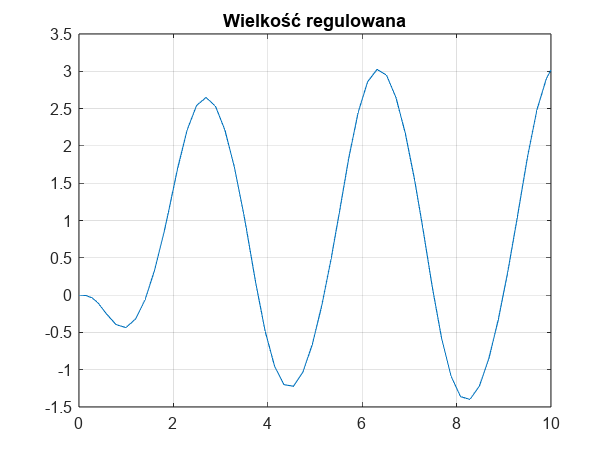


ym = 4.1 * pi;

lab6_(0, ym, licz, mian1);

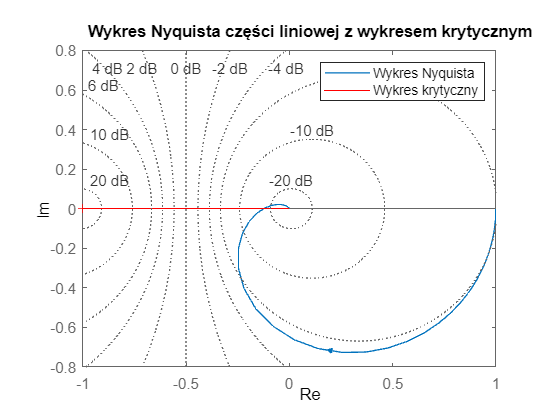

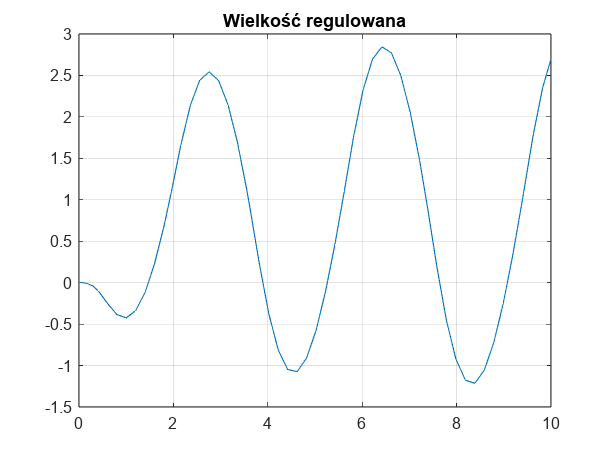


lab6_(0, 33, licz, mian1);

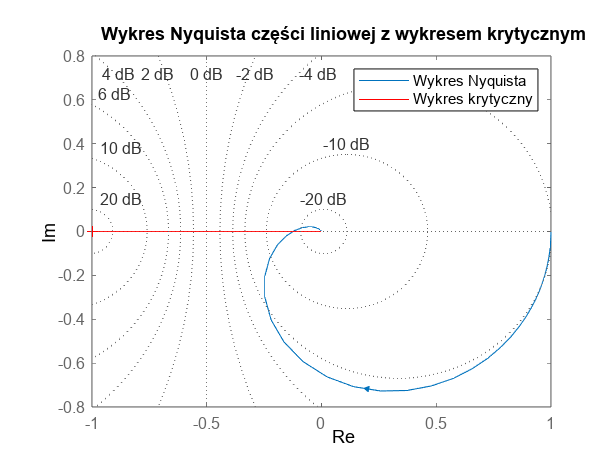


lab6_(0.005, 5.8, licz, mian1);


lab6_(0.005, 12.2, licz, mian1);


lab6_(0.005, 32, licz, mian1);

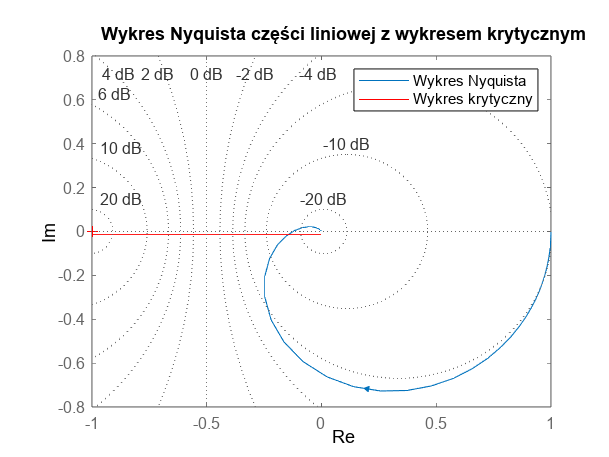


lab6_(0.1, 5.3, licz, mian1);

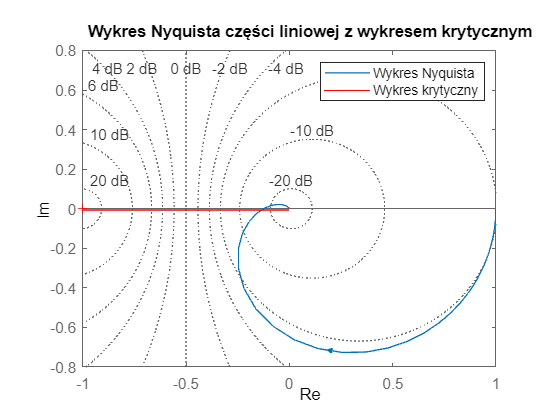


lab6_(0.1, 11.7, licz, mian1);

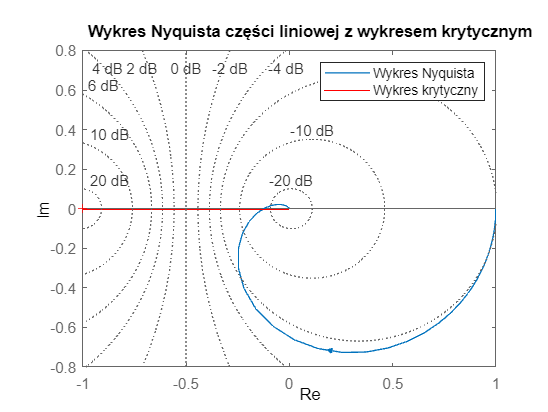


lab6_(0.1, 31.2, licz, mian1);

### Transmitancja druga

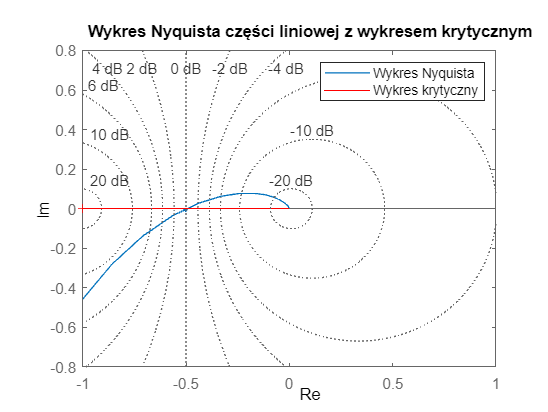

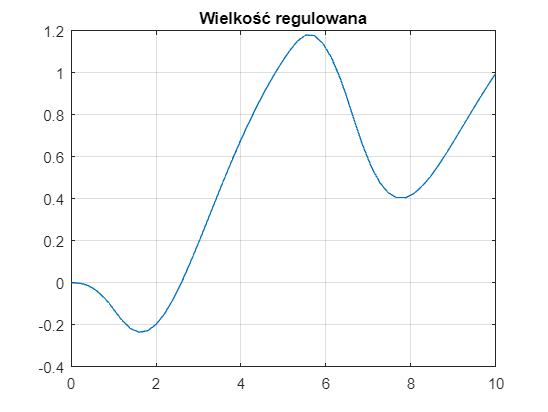

ym = 0.5 * pi;
lab6_(0, ym, licz, mian2);

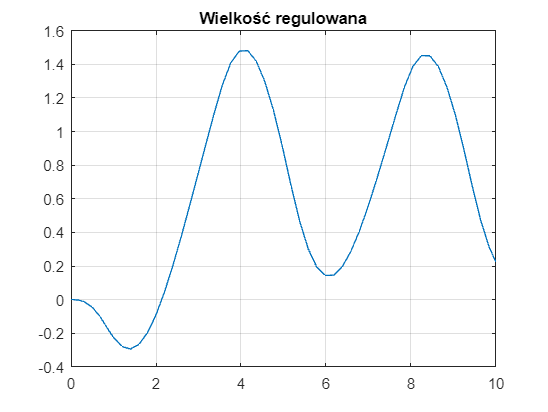


ym = pi;
lab6_(0, ym, licz, mian2);

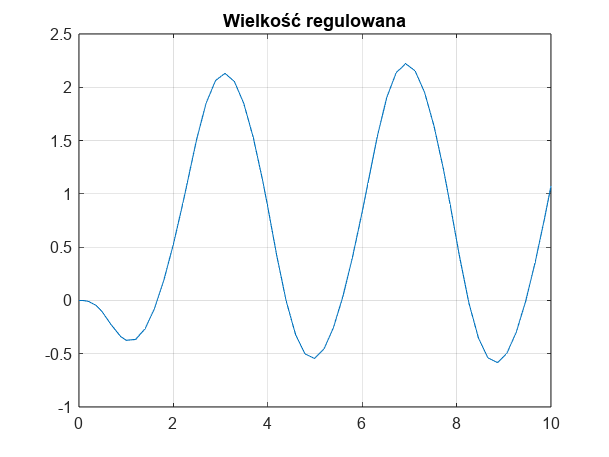


ym = 7.7;
lab6_(0, ym, licz, mian2);

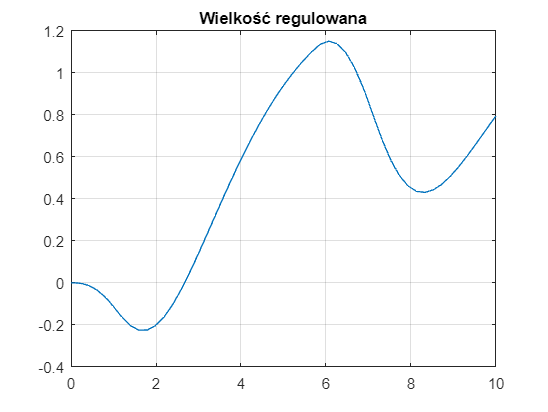


ym = 0.45 * pi;
lab6_(0, ym, licz, mian2);

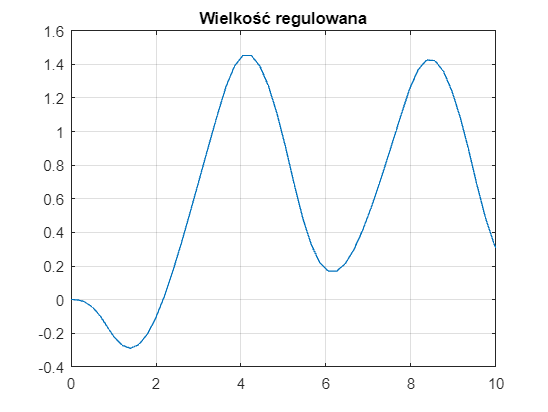


ym = 0.95 * pi;
lab6_(0, ym, licz, mian2);

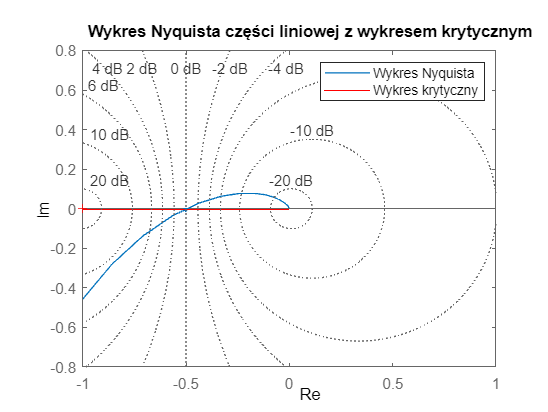

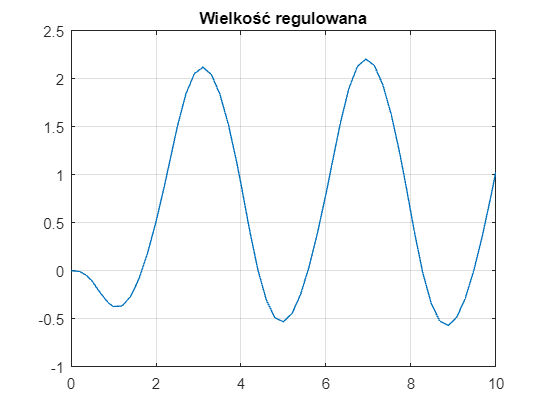


ym = 7.6;
lab6_(0.05, ym, licz, mian2);

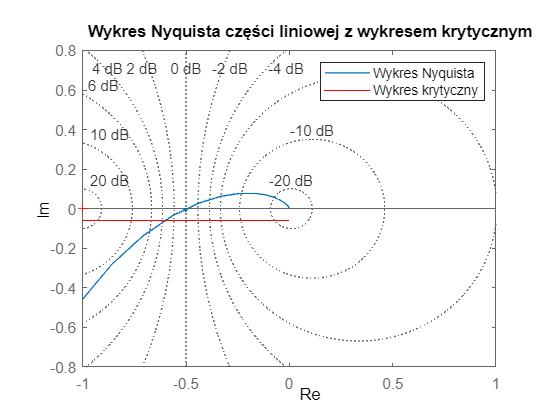

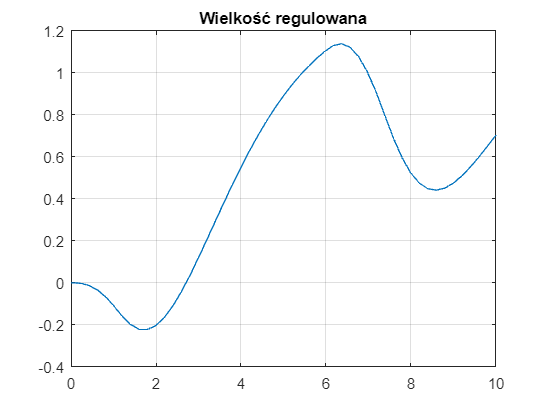


ym = 0.43 * pi;
lab6_(0.1, ym, licz, mian2);

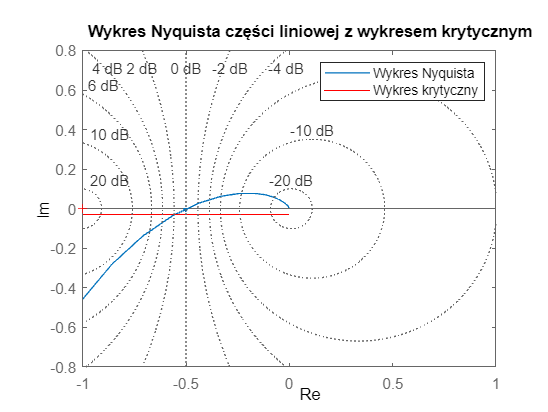

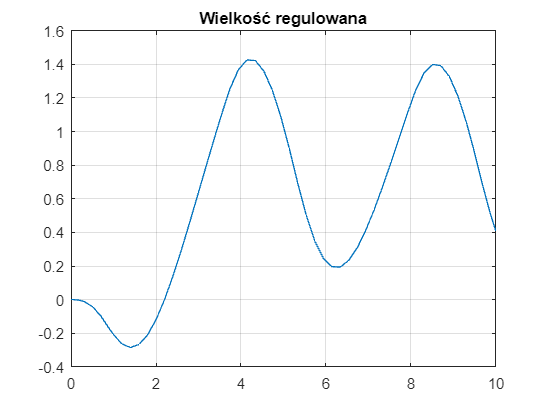


ym = 0.9 * pi;
lab6_(0.1, ym, licz, mian2);

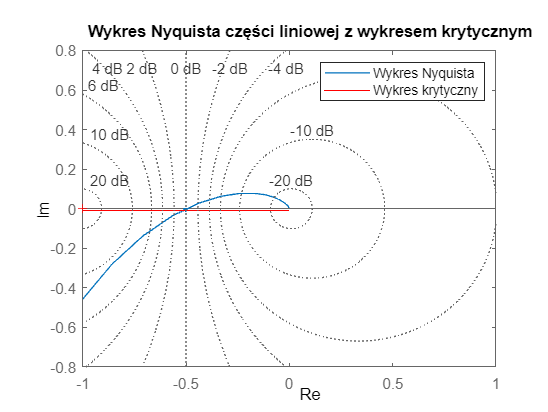

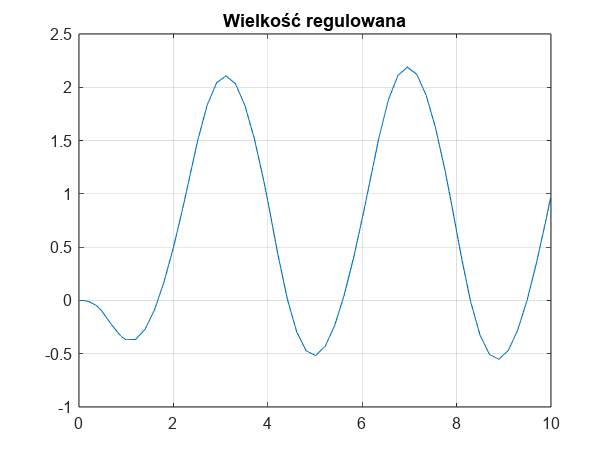


ym = 7.5;
lab6_(0.1, ym, licz, mian2);

### Transmitancja trzecia

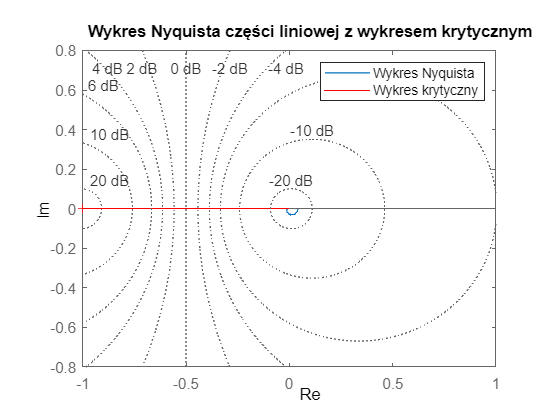

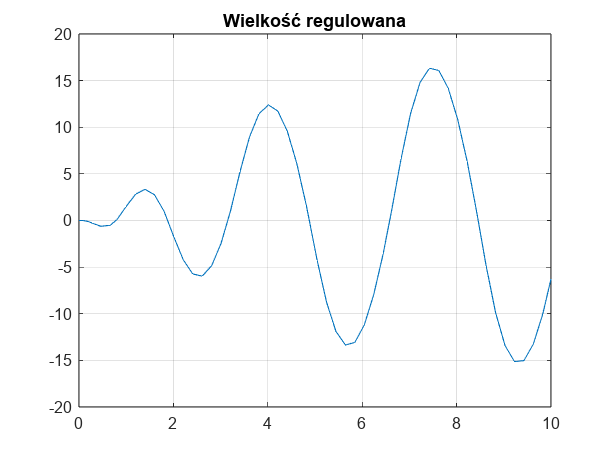

ym = 100;
lab6_(0, ym, licz, mian3);

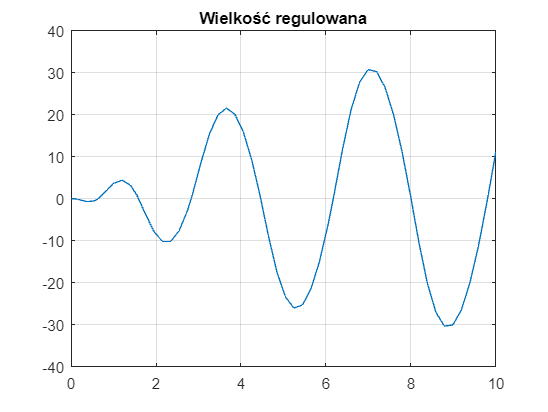


ym = 197;
lab6_(0, ym, licz, mian3);

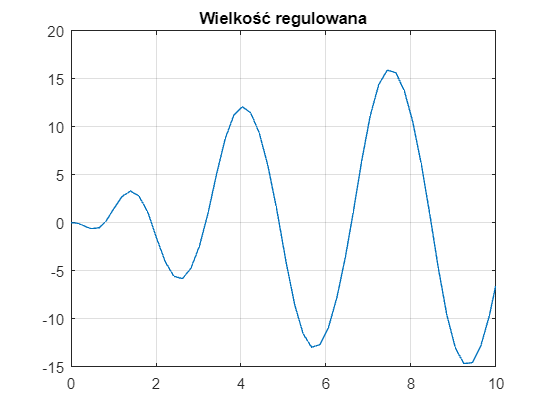


ym = 97;
lab6_(0.05, ym, licz, mian3);

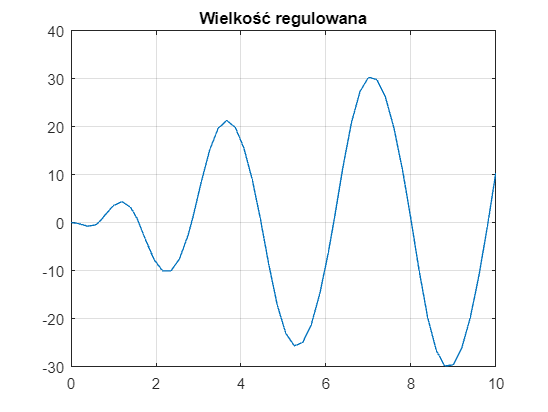


ym = 194;
lab6_(0.05, ym, licz, mian3);

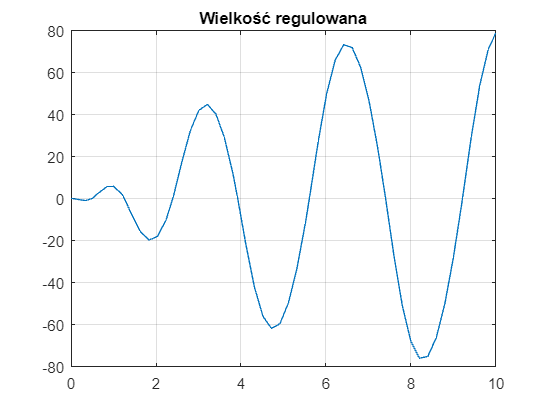


ym = 492;
lab6_(0.05, ym, licz, mian3);

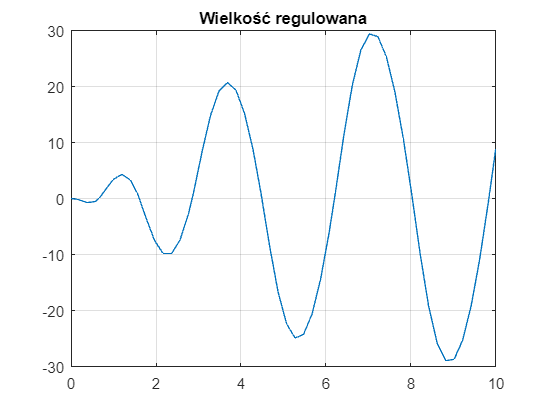


ym = 188;
lab6_(0.1, ym, licz, mian3);

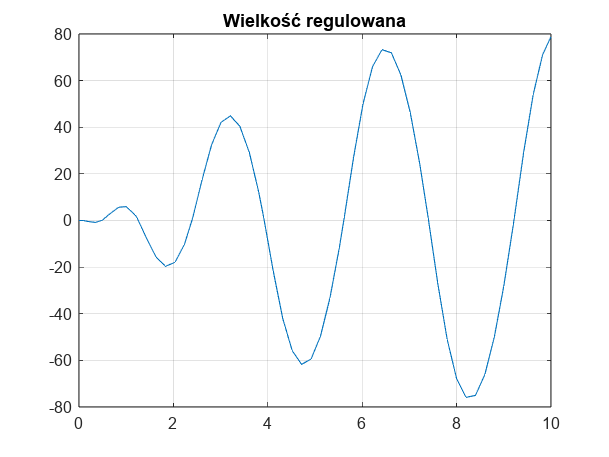


ym = 492;
lab6_(0.1, ym, licz, mian3);

## Wnioski

Laboratorium pozwoliło lepiej zapoznać się z regulatorami dwupołożeniowymi i stabilnością układów. Regulatory bez histerezy nie posiadają częsic urojonej. Zwiększanie histerezy powoduje przemieszczanie się wykresu po osi liczb rzeczywustych. Amplituda cyklu granicznego jest związana ze współczynnikiem ym.